# Proyecto 3

## Identificación de los problemas y requerimientos de las soluciones

### Problema 1

Graficar la distancia al Sol de cada cuerpo durante (por lo menos) una órbita completa. Desplegar sus valores máximo y mínimo y comentarlos.

### Problema 2

Encontrar cuándo estará Marte más cerca a la Tierra en los próximos 10 años y cuál es esta distancia mínima.

### Problema 3

Encontrar cuál es el planeta más cercano a Plutón. ¿Siempre es el mismo?

### Problema 4

Encontrar la rapidez de la Tierra $\bigg ( \frac{km}{h} \bigg )$ alrededor del Sol: mínima, promedio, máxima. ¿Es lógico el resultado?

## Modelos matemáticos de las soluciones

Antes de comenzar, debemos definir algunas constantes entre los diferentes problemas, como la constante de gravitación $G$ en $6.67x10^{-11} \frac{m^3kg}{s^2}$

### Problema 1

Utilizando las leyes de gravitación de Newton podemos llegar al siguiente modelo de las componentes de la fuerza


$$F = G\frac{Mm'}{r^2}(\hat{r})$$



$$F_x = F\frac{x'-x}{r};$$
 
$$F_y = F\frac{y'-y}{r};$$
 
$$F_z = F\frac{z'-z}{r}$$


Ahora, utilizando la segunda ley de Newton podemos hacer lo siguiente


$$F_x = m\frac{d^2x}{dt^2};$$
 
$$F_y = m\frac{d^2y}{dt^2};$$
 
$$F_z = m\frac{d^2z}{dt^2}$$


Combinando ambas ecuaciones podemos llegar al modelo final


$$\frac{d^2x}{dt^2} = Gm'\frac{x'-x}{r^3};$$
 
$$\frac{d^2y}{dt^2} = Gm'\frac{y'-y}{r^3};$$
 
$$\frac{d^2z}{dt^2} = Gm'\frac{z'-z}{r^3}$$



$$r = \sqrt{(x'-x)^2 + (y'-y)^2 + (z'-z)^2}$$


Donde $G$ es la ya discutida constante gravitacional, $m$ y $M$ son las masas del planeta dado y del Sol, respectivamente, $r$ es la distancia entre el planeta y el Sol y $F$ es la fuerza. Ahora podemos usar ecuaciones diferenciales de segundo orden para diseñar un sistema que describa el movimiento de los planetas con respecto al Sol.


$$\frac{d^2x_\alpha}{dt^2} = \sum_{j=1; j\neq\alpha}^{nb} Gm_j \frac{x_j - x_\alpha}{(r_{j,\alpha})^3}$$



$$\frac{d^2y_\alpha}{dt^2} = \sum_{j=1; j\neq\alpha}^{nb} Gm_j \frac{y_j - y_\alpha}{(r_{j,\alpha})^3}$$



$$\frac{d^2z_\alpha}{dt^2} = \sum_{j=1; j\neq\alpha}^{nb} Gm_j \frac{z_j - z_\alpha}{(r_{j,\alpha})^3}$$



$$r_{j,\alpha} = \sqrt{(x_j - x_\alpha)^2 + (y_j - y_\alpha)^2 + (z_j - z_\alpha)^2}$$


donde $\alpha$ se refiere al Sol, $j$ a los diferentes planetas y $nb$ al número de cuerpos (planetas).

### Problema 2

### Problema 3

### Problema 4

## Parámetros base de las soluciones

Utilizando datos del sistema Horizon del 6 de abril de 2018, plantearemos los parámetros base para algunas de nuestras soluciones

Gm=[1.32712440018e20; 
    2.2032e13;
    3.24859e14;
    3.986044418e14;
    4.282837e13;
    1.26686534e17;
    3.7931187e16;
    5.793939e15;
    6.836529e15];

r0=[1.81899e8; 9.83630e8;-1.58778e7;
    -5.67576e10;-2.73592e10;2.89173e9;
    4.28480e10;1.00073e11;-1.11872e9;
    -1.43778e11;-4.00067e10;-1.38875e7;
    -1.14746e11;-1.96294e11;-1.32908e9;
    -5.66899e11;-5.77495e11;1.50755e10;
    8.20513e10;-1.50241e12;2.28565e10;
    2.62506e12;1.40273e12;-2.87982e10;
    4.30300e12;-1.24223e12;-7.35857e10];

v0=[-1.12474e01 ; 7.54876e00 ; 2.68723e-01;
    1.16497e04 ; -4.14793e04 ; -4.45952e03;
    -3.22930e04 ; 1.36960e04 ; 2.05091e03;
    7.65151e03; -2.87514e04 ; 2.08354e00;
    2.18369e04 ; -1.01132e04 ; -7.47957e02;
    9.16793e03 ; -8.53244e03 ; -1.69767e02;
    9.11312e03 ; 4.96372e02 ; -3.71643e02;
    -3.25937e03 ; 5.68878e03 ; 6.32569e01;
    1.47132e03 ; 5.25363e03 ; -1.42701e02];

y0 = [r0; v0];
f = @(t, y) planetsAccel(Gm, y);
h = 60*60*24;
tspan = [0 200*365*h];

## Ejecución de las soluciones

### Problema 1

tic
[t1, y1] = ode45(f, tspan, y0);

toc

Elapsed time is 0.987560 seconds.


tic
[t2, y2] = odeRKF45(f, y0, tspan, h, 0.5e-5, 1000000);
toc

Elapsed time is 3.906847 seconds.


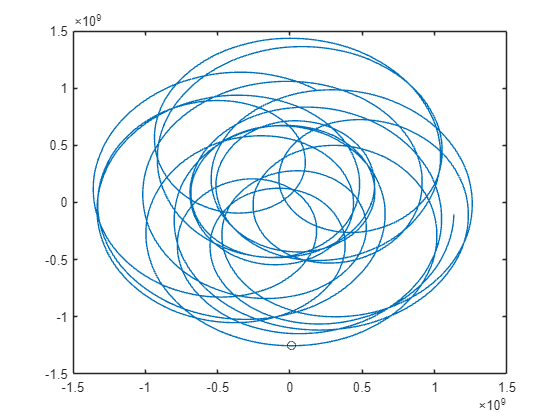

Error using plot
Value not a numeric scalar


planets=["Sol", "Mercurio", "Venus", "Tierra", "Marte", "Júpiter", "Saturno", "Urano", "Neptuno"];
n = length(y2(:,1));
plot(y2(1,:),y2(2,:),'DisplayName',planets(1))
[yx, idx] = min(y2(2, :));
hold on
plot(y2(1, idx), yx,'Marker', 'o', 'Color', 'k', 'LineWidth', '5')

for i=4:3:n/2-2
    plot(y2(i,:), y2(i+1,:),'DisplayName',planets((i-1)/3))
end
legend(planets, 'location', 'best')
hold off

### Problema 2

## Funciones auxiliares

function v = planetsAccel(Gm, y)
    v = zeros(size(y));
    m = length(y);
    v(1:27) = y(m/2 + 1:end);

    for i=1:3:(m/2 - 2)
        v(27+i:27+i+2) = accel(Gm, y, i);
    end
end

function a = accel(Gm, y, alpha)
    a = zeros(3, 1);
    j = 1;
    for i=1:3:(length(y)/2-2)
        if i ~= alpha
            x1 = y(i) - y(alpha);
            x2 = y(i+1) - y(alpha + 1);
            x3 = y(i+2) - y(alpha + 2);
            r = sqrt(x1^2 + x2^2 + x3^2);
            
            Gj = Gm(j);
            G = [Gj*(x1/ r^3); 
                 Gj*(x2/ r^3); 
                 Gj*(x3/ r^3)];
            a = a + G;
        end
        j = j+1;
    end
end

function [t, y] = odeRKF45(f, y0, tspan, h, rTol, maxSteps)
    if ~exist('rTol', 'var'), rTol = 0.5e-5; end
    if ~exist('maxSteps', 'var'), maxSteps = 1000; end

    i = 1;
    t0 = tspan(1); tf = tspan(2);
    t(i) = t0;
    y(:, i) = y0;

    while t(end) < tf && i < maxSteps
        if t(end)+1.1*h >= tf
            h = tf-t(end);
        end

        [z, r] = stepRKF45(f, t(end), y(:, end), h);
        if r <= rTol
            t(end+1) = t(end) + h;
            y(:, end+1) = z;
            i = i+1;
        end

        h = 0.9*h*nthroot(rTol/r, 5);
    end
end

function [z, r] = stepRKF45(f, t, w, h)
    s1 = f(t, w);
    s2=f(t+(1/4)*h,w+(1/4)*h*s1);
    s3 = f(t + 3/8*h, w + 3/32*h*s1 + 9/32*h*s2);  
    s4 = f(t + 12/13*h, w + 1932/2197*h*s1 - 7200/2197*h*s2 + 7296/2197*h*s3); 
    s5 = f(t+h, w + 439/216*h*s1 - 8*h*s2 + 3680/513*h*s3 - 845/4104*h*s4);
    s6 = f(t + 1/2*h, w - 8/27*h*s1 + 2*h*s2 - 3544/2565*h*s3 + 1859/4104*h*s4 - 11/40*h*s5);  
    
    wP = w;
    w = wP + h*((25/216)*s1 + (1408/2565)*s3 + (2197/4104)*s4 - (1/5)*s5);           
    z = wP + h*((16/135)*s1 + (6656/12825)*s3 + (28561/56430)*s4 - (9/50)*s5 + (2/55)*s6);
    r = norm((z-w)./z,Inf);
end

## Referencias